# Chapter 17:  Sparse Recovery from One-Bit Observations

close all; clear all;

## Estimating the direction from one-bit observations

Here, the binary observations made on a vector $x \in \mathbb{R}^N$ with $\|x\|_2 = 1$ and $\|x\|_0 \le s$ take the form


$$y_i = {\rm sgn}\big( \langle a^{(i)}, x \rangle \big),
\qquad i = 1,\ldots,m.$$


% generate a normalized s-sparse vector together with its one-bit observation vector
N = 200;                % ambient dimension
s = 8;                  % sparsity level
m = 20000;              % number of observations
% create the vector x to be recovered
x = zeros(N,1);
supp = sort(randperm(N,s)); 
x(supp) = randn(s,1);
x = x/norm(x);         
% produce the one-bit observation vector y 
A = sqrt(pi/2)/m*randn(m,N); 
y = sign(A*x);

#### The direction of x is well approximated by the outputs of the hard thresholding and the linear programming procedures, namely by

- 
$$x_{\rm ht} = H_s(A^\top y);$$


- 
$$x_{\rm lp} = \underset{z.c \in \mathbb{R}^N}{\rm argmin} \; \sum_{i=1}^m c_i \quad \mbox{subject to} \quad 
-c \le z \le c, \quad \sum_{i=1}^m y_i \langle a^{(i)}, z \rangle = 1,
\quad y_i  \langle a^{(i)}, z \rangle \ge 0, \; i=1,\ldots,m.$$


tic;
x_ht = zeros(N,1);
aux = A'*y;
[~,idx] = sort(abs(aux),'descend');
x_ht(idx(1:s)) = aux(idx(1:s));
t_ht = toc;
rel_error_ht = norm(x-x_ht);
tic;
cvx_begin quiet
variable x_lp(N)
variable c(N)
minimize sum(c)
subject to
sum(y.*(A*x_lp)) == 1;
y.*(A*x_lp) >= 0;
c + x_lp >= 0;
c - x_lp >= 0;
cvx_end
t_lp = toc;
rel_error_lp = norm(x-x_lp);
fprintf(['Hard thresholding took  %.3f sec to approximate x with (relative) L2-error %.2s\n',...
    'Linear programming took %.2f sec to approximate x with (relative) L2-error %.2s\n'],...
    t_ht,rel_error_ht,t_lp,rel_error_lp)

Hard thresholding took  0.010 sec to approximate x with (relative) L2-error 2.64e-02
Linear programming took 20.62 sec to approximate x with (relative) L2-error 5.51e-03


## Dependence of the estimation error with the number of one-bit observations

Introducing the ratio $\lambda = \frac{m}{s \ln(eN/s)}$, one expects a behavior of the type $\epsilon \le  D \lambda^{-c}$ for the estimation error $\epsilon
$, i.e. $\ln(\epsilon) \le -c \ln(\lambda) + \ln(D)$.

For hard thresholding (the only procedure tested below as linear programming would take too long), Theorem 17.2 reveals that one can take $c = 1/6$, which is in fact improvable to $c=1/2$ (see Exercise 17.2).

N = 200;  
s = 8;
n_tests = 250;
m_min = 10000;
m_max = 30000;
m_inc = 1000;
ratio = zeros(1,(m_max-m_min)/m_inc+1);
error_ht = zeros(n_tests,(m_max-m_min)/m_inc+1);
tic;
for t = 1:n_tests
    x = zeros(N,1);
    supp = sort(randperm(N,s)); 
    x(supp) = randn(s,1);
    x = x/norm(x);
    for m = m_min:m_inc:m_max
        A = sqrt(pi/2)/m*randn(m,N); 
        y = sign(A*x);
        x_ht = zeros(N,1);
        aux = A'*y;
        [~,idx] = sort(abs(aux),'descend');
        x_ht(idx(1:s)) = aux(idx(1:s));
        ratio((m-m_min)/m_inc+1) = m/s/log(N/s);
        error_ht(t,(m-m_min)/m_inc+1) = norm(x-x_ht);
    end
end
t_experiment = toc;

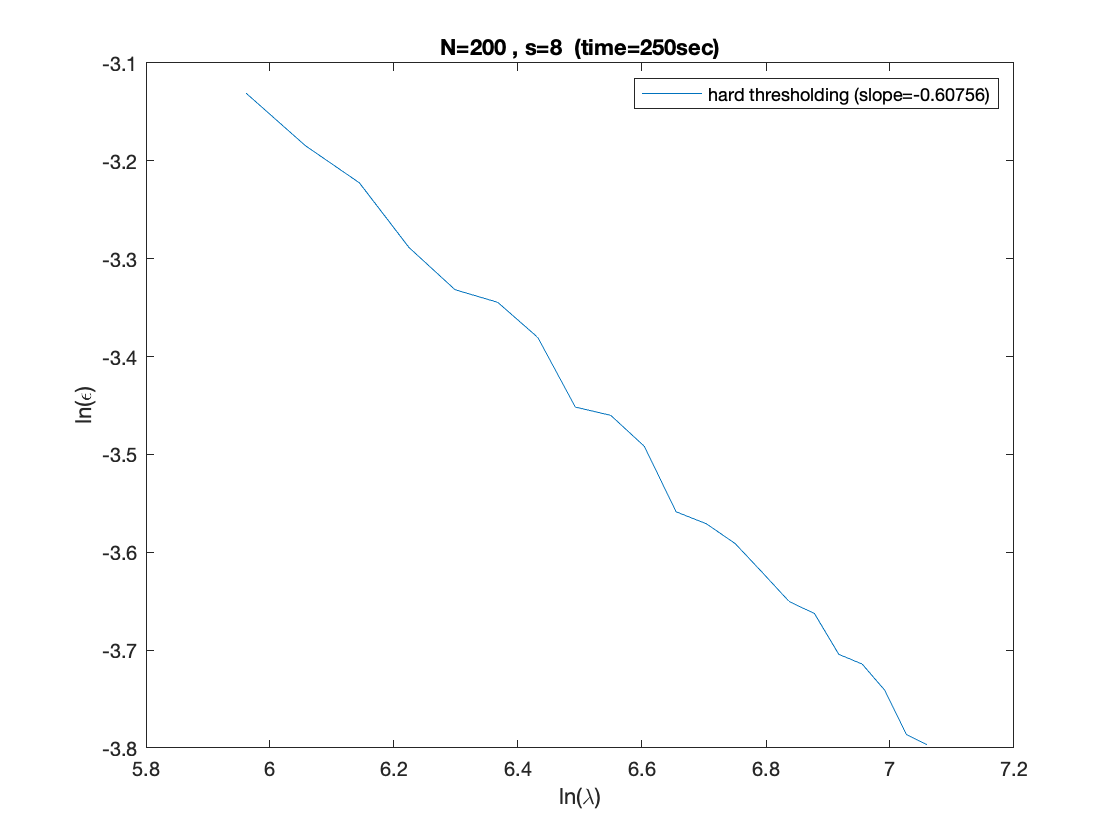

% visualize the result
slope_ht_aux = polyfit(log(ratio),log(mean(error_ht)),1);
slope_ht = slope_ht_aux(1);
figure(1)
plot(log(ratio),log(mean(error_ht)))
xlabel('ln(\lambda)')
ylabel('ln(\epsilon)')
legend(strcat('hard thresholding (slope=',num2str(slope_ht),')'))
title(strcat('N=',num2str(N), 32, ', s=', num2str(s), 32, ' (time=', num2str(round(t)), 'sec)'))

## Estimating both the direction and the magitude from one-bit observations

Here, the binary observations made on a vector $x \in \mathbb{R}^N$ with $\|x\|_2 \le 1$ and $\|x\|_0 \le s$ take the form


$$y_i = {\rm sgn}\big( \langle a^{(i)}, x \rangle - \theta_i \big),
\qquad i = 1,\ldots,m.$$


The vector $x \in \mathbb{R}^N$ is fully approximated through the estimation of the direction of the augmented vector $\tilde{x} = [x;1] \in \mathbb{R}^{N+1}$ via "lifted" versions of the hard thresholding and of the linear programming procedures.

% select problem sizes
N = 200;  
s = 8;
m = 20000;
% create the sparse vector x to be recovered
x = zeros(N,1);
supp = sort(randperm(N,s)); 
x(supp) = randn(s,1);
x = rand*x/norm(x);
% produce the observation vector y 
A = sqrt(pi/2)/m*randn(m,N); 
theta = sqrt(pi/2)/m*randn(m,1);
y = sign(A*x-theta);
A_tilde = [A -theta];
% estimation via lifted hard threholding
tic;
x_tilde_ht = zeros(N+1,1);
aux = A_tilde'*y;
[~,idx] = sort(abs(aux),'descend');
x_tilde_ht(idx(1:s+1)) = aux(idx(1:s+1));
x_ht = x_tilde_ht(1:N)/x_tilde_ht(N+1);
t_ht = toc;
rel_error_ht = norm(x - x_ht)/norm(x);
% extimation via lifted linear progamming
tic;
cvx_begin quiet
variable x_tilde_lp(N+1)
variable c(N+1)
minimize sum(c)
subject to
sum(y.*(A_tilde*x_tilde_lp)) == 1;
y.*(A_tilde*x_tilde_lp) >= 0;
c + x_tilde_lp >= 0;
c - x_tilde_lp >= 0;
cvx_end
x_lp = x_tilde_lp(1:N)/x_tilde_lp(N+1);
t_lp = toc;
rel_error_lp = norm(x - x_lp)/norm(x);
fprintf(['Hard thresholding took  %.3f sec to approximate x with (relative) L2-error %.2s\n',...
    'Linear programming took %.2f sec to approximate x with (relative) L2-error %.2s\n'],...
    t_ht,rel_error_ht,t_lp,rel_error_lp)

Hard thresholding took  0.009 sec to approximate x with (relative) L2-error 1.20e-01
Linear programming took 20.57 sec to approximate x with (relative) L2-error 1.14e-02
